# SDR Frequency Modulation Lab

Charlotte Ramiro and Lilo Heinrich

### Exercise 1

load SDR_FM_Lab.mat

#### Part C

Using the RTL-SDR tuned to fc = 90.8MHz, and with a sample rate of 300,000, please collect 5-10 seconds worth of data. Plot the FFT of yI . Does it match what you predicted in (a)?

Plot the FFT of y_I(t) which is Y_I(f)

Y_I = fftshift(fft(y_I));
f = linspace(-fs/2, fs/2*(length(y_I)-1)/length(y_I), length(y_I));


ans = -150000

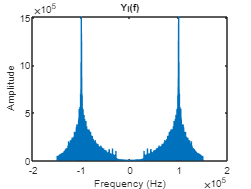

figure(1); hold on; clf;
plot(f, abs(Y_I))
title("Y_I(f)")
xlabel("Frequency (Hz)")
ylabel("Amplitude")

#### Part D

Plot the time domain signal yI from Part (c). By zooming into different parts of the time-domain signal, find a portion of the signal that clearly indicates that it is an FM signal (you should be able to find a portion of the signal which has varying frequencies). You should submit a plot of this with your report.

Plot y_I(t)

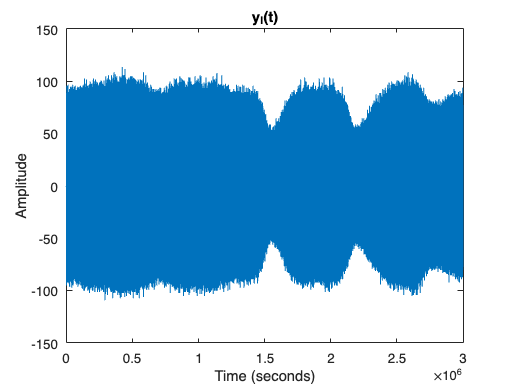

figure(2); clf;
plot(y_I)
title("y_I(t)")
xlim([0,length(y_I)])
xlabel("Time (seconds)")
ylabel("Amplitude")

Plot y_I(t) zoomed in to see an area of frequency modulation

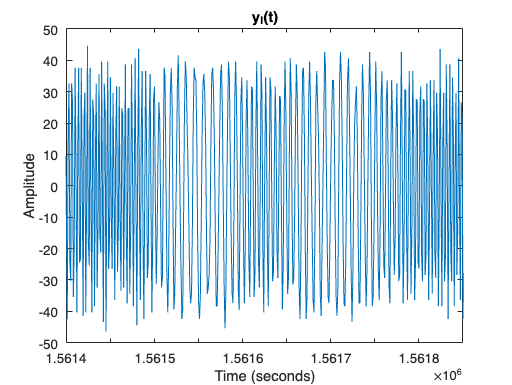

figure(2); clf;
plot(y_I)
title("y_I(t)")
xlim([1.5614e6, 1.56185e6])
xlabel("Time (seconds)")
ylabel("Amplitude")

#### Part E

Take the derivative of the signal, and zero out its negative components. This operation simulates the derivative followed by the diode portion of the envelope detector. Please normalize this signal so that its maximum value is 1. Please plot the resulting signal. 

Take the derivative of y_I(t) which is dy_I(t)/dt

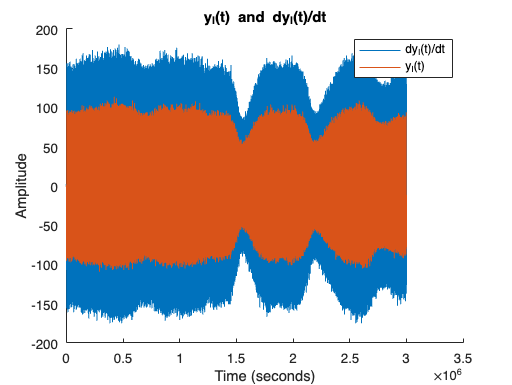

y_I_deriv = diff(y_I);

figure(3); clf;
hold on;
plot(y_I_deriv)
plot(y_I)
legend('dy_I(t)/dt', 'y_I(t)')
title("y_I(t) and dy_I(t)/dt")
xlabel("Time (seconds)")
ylabel("Amplitude")

Zero out the negative components of dy_I(t)/dt

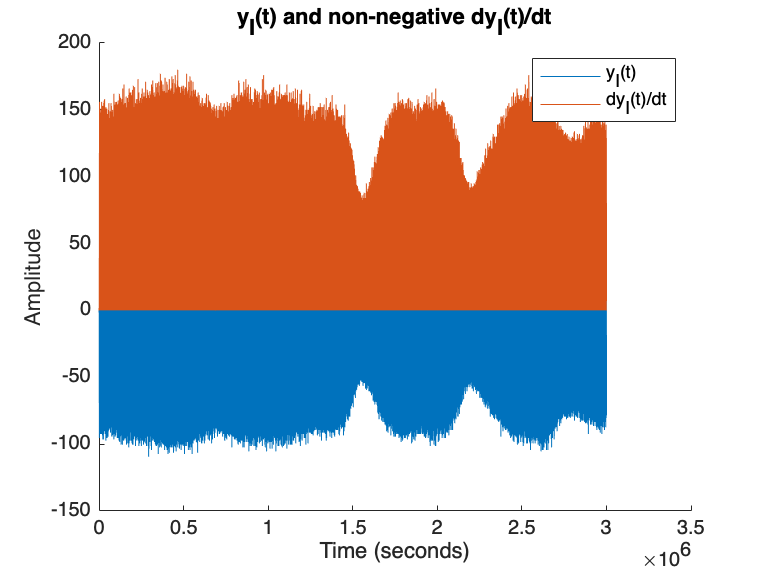

y_I_deriv_nonneg = max(y_I_deriv, 0);

figure(4); clf; hold on;
plot(y_I)
plot(y_I_deriv_nonneg)
legend('y_I(t)', 'dy_I(t)/dt')
title("y_I(t) and non-negative dy_I(t)/dt")
xlabel("Time (seconds)")
ylabel("Amplitude")

Normalize this signal so that its maximum value is 1 and plot it

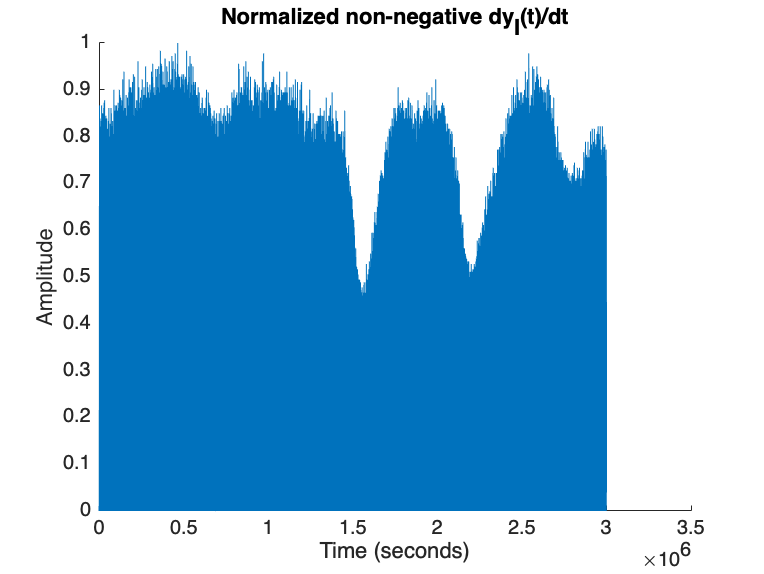

y_I_deriv_nonneg_max = max(y_I_deriv_nonneg);
y_I_deriv_nonneg_norm = y_I_deriv_nonneg/y_I_deriv_nonneg_max;

figure(5); clf; hold on;
plot(y_I_deriv_nonneg_norm)
title("Normalized non-negative dy_I(t)/dt")
xlabel("Time (seconds)")
ylabel("Amplitude")

#### Part F

Low pass filter the signal from Part (e), and normalize it so that its maximum value is 1. Please plot this signal on the same axes as the previous part. Zoom in to a portion of the signal which illustrates how the diode followed by low pass filter tracks the envelope of the derivative FM signal.

Take the result of part (e), FFT it into the frequency domain, and lowpass filter it

y_I_lowpass = lowpass(y_I_deriv_nonneg_norm, 10e3, fs);

Normalize the resulting signal, and plot it on the same axes as part (e)

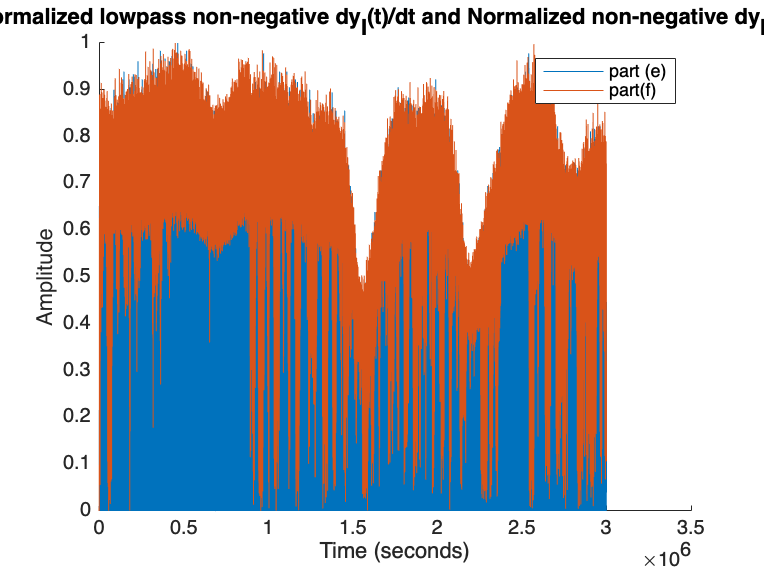

y_I_lowpass_max = max(y_I_lowpass);
y_I_lowpass_norm = y_I_lowpass/y_I_lowpass_max;

figure(); clf; hold on;
plot(y_I_deriv_nonneg_norm)
plot(abs(y_I_lowpass_norm))
legend('part (e)', 'part(f)')
title("Normalized lowpass non-negative dy_I(t)/dt and Normalized non-negative dy_I(t)/dt")
xlabel("Time (seconds)")
ylabel("Amplitude")

Zoom in to a portion of the signal which illustrates how the diode followed by low pass filter tracks the envelope of the derivative FM signal

#### Part G

Subtract the mean out of the signal in the previous part, normalize it so that its maximum value is 0.1 to control volume, and decimate it by a factor of 4 using e.g. MATLAB’s decimate function. The decimation reduces the sample rate to a value that your computer can handle comfortably for audio. Using MATLAB’s sound command listen to the resulting signal, and make note of its features to compare to the next part. Note that you will have to specify the sampling frequency in the call to sound, which will be 300000/4 here. 

Subtract the mean out of the signal from part (f)

mean_y_I_lowpass_norm = mean(y_I_lowpass_norm)

mean_y_I_lowpass_norm = 0.6521

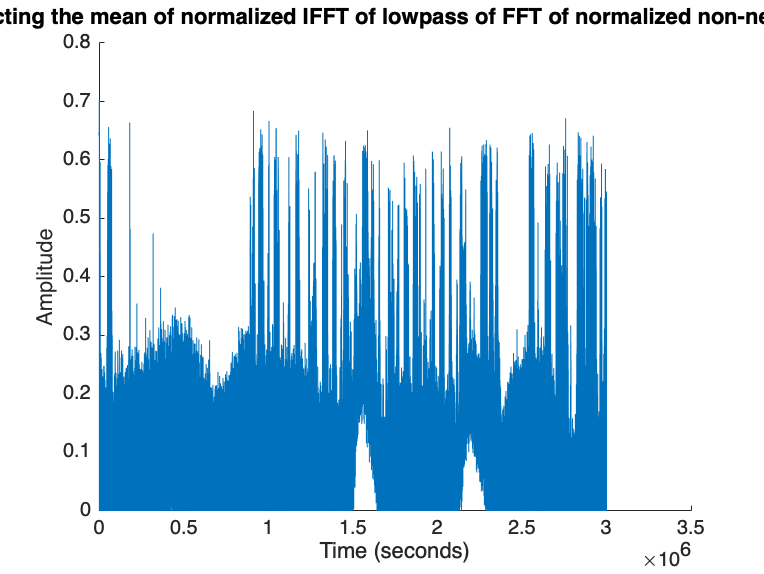

y_I_meanless = y_I_lowpass_norm - mean_y_I_lowpass_norm;

figure(); clf; hold on;
plot(abs(y_I_meanless))
title("After subtracting the mean of normalized IFFT of lowpass of FFT of normalized non-negative dy_I(t)/dt")
xlabel("Time (seconds)")
ylabel("Amplitude")

Normalize the new signal

max_y_I_meanless = max(y_I_meanless)

max_y_I_meanless = 0.3479

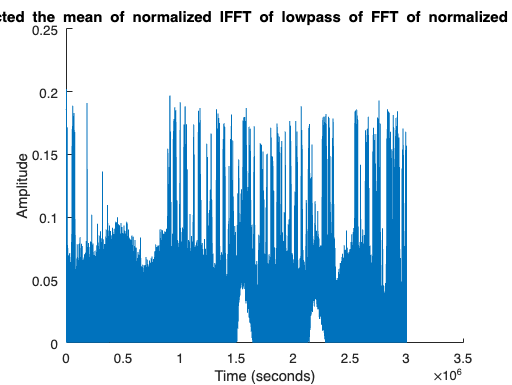

y_I_meanless_norm = y_I_meanless/max_y_I_meanless/10;

figure(); clf; hold on;
plot(abs(y_I_meanless_norm))
title("Normalized subtracted the mean of normalized IFFT of lowpass of FFT of normalized non-negative dy_I(t)/dt")
xlabel("Time (seconds)")
ylabel("Amplitude")

Decimate the new normalized signal

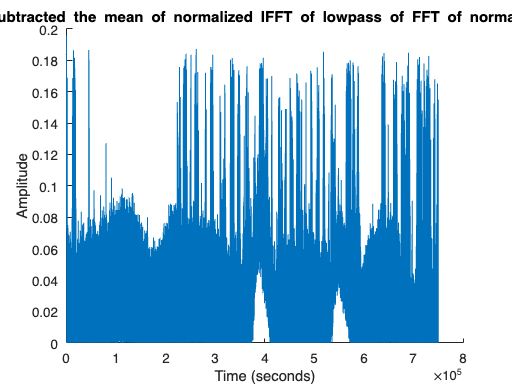

y_I_meanless_norm_decimated = decimate(y_I_meanless_norm, 4);

figure(); clf; hold on;
plot(abs(y_I_meanless_norm_decimated))
title("Decimated normalized subtracted the mean of normalized IFFT of lowpass of FFT of normalized non-negative dy_I(t)/dt")
xlabel("Time (seconds)")
ylabel("Amplitude")

Play the final signal

decimated_fs = fs/4;
sound(y_I_meanless_norm_decimated, decimated_fs);

### Exercise 2

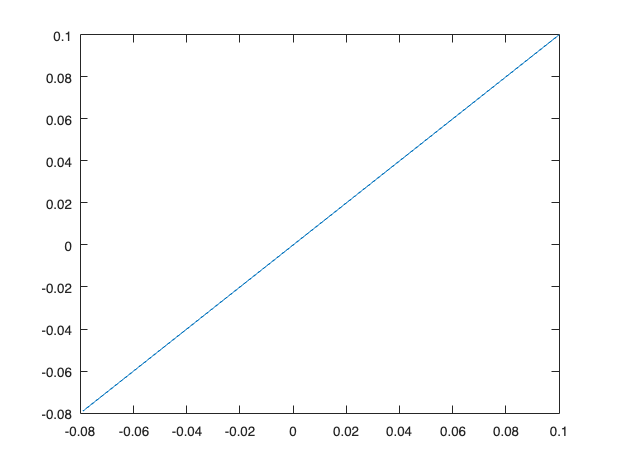

pause(10)
fc = 90.8e6; % fc already exists from loading in the .mat data file
y_Q_deriv = diff(y_Q);

m_hat = (y_Q_deriv .* y_I(1:3000319)) - (y_I_deriv.*y_Q(1:3000319));

m_hat_norm = max(m_hat, 0) ./ max(m_hat);
m_hat_norm_safe = m_hat_norm - mean(m_hat_norm);

m_hat_norm_safe_norm = m_hat_norm_safe ./ (max(m_hat_norm_safe) / .1);
plot(m_hat_norm_safe_norm(1:3000319), m_hat_norm_safe_norm);


m_hat_decimated = decimate(m_hat_norm_safe_norm, 4);
sound(m_hat_decimated, 300000/4)